dr = 1;
R_a = 10;
R_b = 1:dr:10^6;
uC = [1 2.2 3.3 4.7 10] .* 10^-6;
nC = [1 2.2 4.7 10 22 47 100 220 470] .* 10^-9;
pC = [1 2.2 4.7 10 22 47 100 220 470] .* 10^-12;
test_C = [22 47 100 220 470 1000] .* 10^-9;


## Frequency

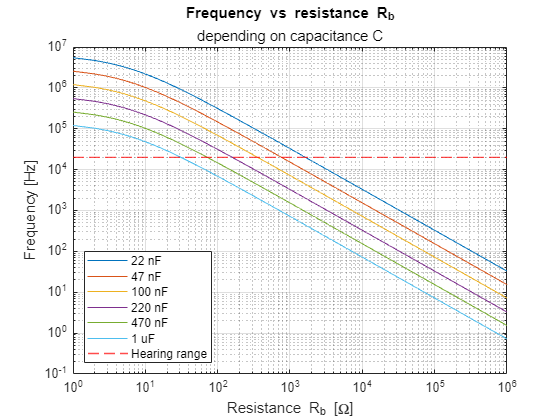

plotfvsR(R_a, R_b, test_C);

## Duty cycle

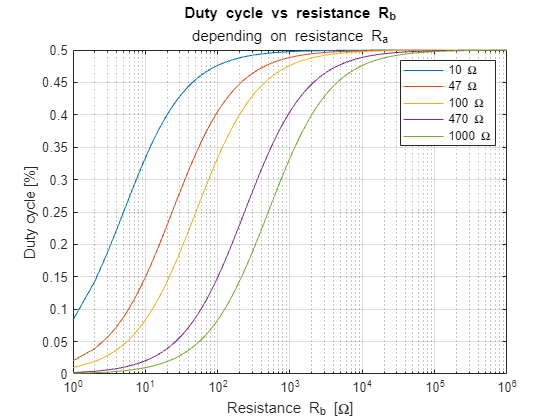

test_R_a = [10 47 100 470 1000];
for r_a = 1:size(test_R_a, 2)
    dc = duty_cycle(test_R_a(r_a), R_b);    
    semilogx(R_b, dc, "DisplayName", join([string(test_R_a(r_a)) "\Omega"]));
    hold on;
end
legend("show");
title("Duty cycle vs resistance R_b");
subtitle("depending on resistance R_a");
xlabel("Resistance R_b [\Omega]");
ylabel("Duty cycle [%]");
grid on;
hold off;

## notes

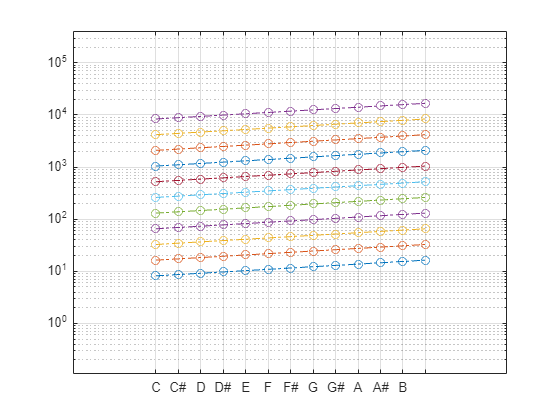

A_4 = 440;
notes_index = 0:1:12;
for k = 1:1:11
    notes = 2.^((notes_index - 69)/12) .* A_4;
    semilogy(0:12, notes, 'o-.');
    notes_index = notes_index + 12;
    hold on;
end
xticks(0:12);
xticklabels(["C", "C#", "D", "D#", "E", "F", "F#", "G", "G#", "A", "A#", "B"]);
grid on;
hold off;

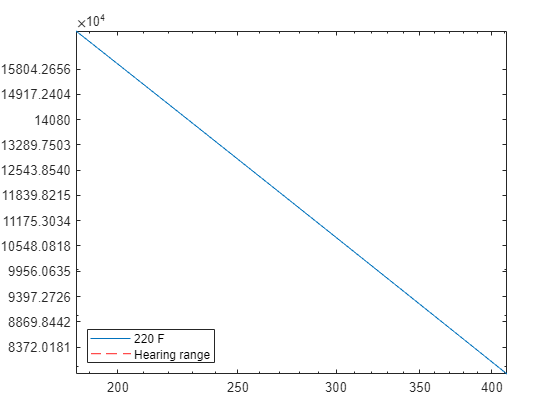

c = 220 * 10^-9;
r_b = 10:10^6;
r_a = 10;
T = period(r_a, r_b, c);
frequency1 = 1./T;
loglog(r_b, frequency1, "DisplayName", "220 F");
yline(20000, "Color","red", "LineWidth", 1, "LineStyle","--", "DisplayName", "Hearing range");
legend("Location","southwest")
ylim([8372-500 16744+500]);
notes_index = 120:131;
notes = 2.^((notes_index - 69)/12) .* A_4;
yticks(notes);